%Loading the Data
load data\mnist_train.csv
load data\mnist_test.csv

%Showing n-th Image
n = 1;
img_matrix = reshape(mnist_train(n, 2:end), [28 28])'

img_matrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     3    18    18    18   126   136   175    26   166   255   247   1

digit = mnist_train(n, 1)

digit = 5

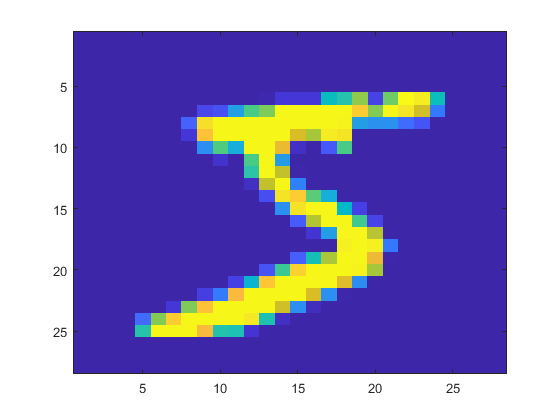

image(img_matrix)

%One Hot Encoding of Labels
labels = mnist_train(:, 1);
labels = categorical(labels);
labels = onehotencode(labels, 2);

%Building the Neural Network
layers = [784 16 16 10]

layers =    784    16    16    10


num_hidden = length(layers)-2;

weights = {};
for i = 2:length(layers)
    weights = {weights{:}, -1 + 2.*rand(layers(i-1), layers(i))'};
end

biases = {};
for i = 2:length(layers)
    biases = {biases{:}, -1 + 2.*rand(layers(i),1)};
end

%Variables
lr = 0.05;
epochs = 10;

C = [];
for epoch = 1:epochs
epoch

for iter = 1:length(mnist_train)

%Setting Activations
activations = {1/256 * mnist_train(iter, 2:end)'};
for i = 2:length(layers)
    activations = {activations{:}, zeros(layers(i), 1)};
end

epoch = 1

epoch = 2

epoch = 3

epoch = 4

epoch = 5

epoch = 6

epoch = 7

epoch = 8

epoch = 9

epoch = 10

epoch = 11

epoch = 12

epoch = 13

epoch = 14

epoch = 15

epoch = 16

epoch = 17

epoch = 18

epoch = 19

epoch = 20

epoch = 21

epoch = 22

epoch = 23

epoch = 24

epoch = 25

epoch = 26

epoch = 27

epoch = 28

epoch = 29

epoch = 30

%Pass Forward
for l = 2:length(layers)
    activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
end

%Error Measure
%C(end+1) = (activations{end}-labels(iter,:)')'*(activations{end}-labels(iter,:)');

%Backprop in last layer
% l = 4;
% dzw = activations{l-1};
% daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1});
% dCa = 2 * (activations{end}-labels(iter,:)');
% 
% dCw_l = (dzw * (daz * dCa)')';
% dCb_l = daz * dCa;
% 
% dCw = {};
% dCb = {};
% dCw = {dCw{:}, dCw_l};
% dCb = {dCb{:}, dCb_l};

%Backpropogation in hidden layer
% for l = 3:-1:2
% dzw = activations{l-1};
% daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1});
% %dCa = weights{l} * dsigmoid(weights{l}*activations{l-1}+biases{l}) * 2*(activations{l}-labels(iter,:))
% 
% dCw_h = daz*dzw';
% dCb_h = daz;
% 
% dCw = {dCw_h, dCw{:}};
% dCb = {dCb_h, dCb{:}};
% end

% %Updating the weights and biases
% for l = 1:(length(layers)-1)
%     weights{l} = weights{l} - lr*dCw{l};
%     biases{l} = biases{l} - lr*dCb{l};
% end

%Calculating Error
error = (labels(iter,:)' - activations{end});

%Propagate Error Back
delta_last = error .* dsigmoid(weights{3} * activations{3} + biases{3});
% 
% delta_hidden_2 = (weights{3}' * delta_last) .* dsigmoid(weights{2} * activations{2} + biases{2})
% 
% delta_hidden_1 = (weights{2}' * delta_hidden_2) .* dsigmoid(weights{1} * activations{1} + biases{1})

delta = {delta_last};
for l = num_hidden:-1:1
    delta = {(weights{l+1}' * delta{1}) .* dsigmoid(weights{l} * activations{l} + biases{l}), delta{:}};
end

%Update Weights and Biases
% weights{3} = weights{3} + lr * delta_last * activations{3}'
% biases{3} = biases{3} + lr * delta_last
% 
% weights{2} = weights{2} + lr * delta_hidden_2 * activations{2}'
% biases{2} = biases{2} + lr * delta_hidden_2
% 
% weights{1} = weights{1} + lr * delta_hidden_1 * activations{1}'
% biases{1} = biases{1} + lr * delta_hidden_1

for l = length(layers)-1:-1:1
    weights{l} = weights{l} + lr * delta{l} * activations{l}';
    biases{l} = biases{l} + lr * delta{l};
end

end

%Verifying the accuracy

right = 0;
wrong = 0;

for iter = 1:length(mnist_test)
    %Pass Forward
    activations = {1/256 * mnist_test(iter, 2:end)'};
    for i = 2:length(layers)
        activations = {activations{:}, zeros(layers(i), 1)};
    end
    for l = 2:length(layers)
        activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
    end
    
    %Get Prediction
    [value, index] = max(activations{end});
    label = index - 1;
    
    %Check Prediction
    if label == mnist_test(iter, 1)
        right = right + 1;
    else
        wrong = wrong + 1;
    end
end

accuracy = right/(right+wrong)

accuracy = 0.8783

accuracy = 0.9093

accuracy = 0.9197

accuracy = 0.9247

accuracy = 0.9259

accuracy = 0.9284

accuracy = 0.9305

accuracy = 0.9328

accuracy = 0.9340

accuracy = 0.9340

accuracy = 0.9346

accuracy = 0.9354

accuracy = 0.9362

accuracy = 0.9359

accuracy = 0.9367

accuracy = 0.9372

accuracy = 0.9373

accuracy = 0.9378

accuracy = 0.9381

accuracy = 0.9380

accuracy = 0.9375

accuracy = 0.9383

accuracy = 0.9379

accuracy = 0.9385

accuracy = 0.9379

accuracy = 0.9382

accuracy = 0.9389

accuracy = 0.9388

accuracy = 0.9387

accuracy = 0.9380


end

%Defining Functions

function y = sigmoid(z)
    y = (1./(1+exp(-z)));
end

function y = dsigmoid(z)
    y = sigmoid(z) .* (1-sigmoid(z));
end